## **Cargar la base de datos**

%ruta del data set
datasetPath = 'C:/Users/tsab/OneDrive/Documentos/tomato';
%valid y train path
trainPath = 'C:/Users/tsab/OneDrive/Documentos/tomato/train';
valPath   = 'C:/Users/tsab/OneDrive/Documentos/tomato/valid';

imdsTrain = imageDatastore(trainPath, ...
                      'IncludeSubfolders', true, ... %buscar en carpetas
                      'LabelSource', 'foldernames');
imdsVal = imageDatastore(valPath, ...
                      'IncludeSubfolders', true, ... %buscar en carpetas
                      'LabelSource', 'foldernames');


## **Mostrar ejemplos de la base de datos **

figure; %ventana de img
perm = randperm(1000,20) %num aleatorios (20) del 1-1000

perm =    921   246    78   283   302   620   579   688   143   345   618   850   466   682    93    57   812    90   203   779


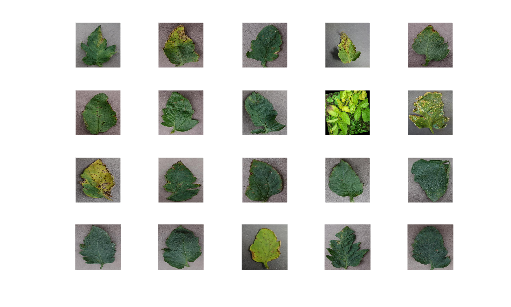

for i = 1:20
    subplot(4,5,i) %en fig de 4 x 5 coloca i (imagen random)
    imshow(imdsTrain.Files{perm(i)});
end

## **Calcular el numero de imagenes que tiene cada categoría **

Cuando cargas el dataset con `imageDatastore`, MATLAB automáticamente asigna **labels** según el nombre de cada carpeta.

Eso significa que cada imagen en `imds` tiene una etiqueta en `imds.Labels`.

%contar imágenes por categoría 
%ALLlabelCount = countEachLabel(imds);
TrainLabelCount = countEachLabel(imdsTrain)

TrainLabelCount = 11×2 table
                   Label                    Count
    ____________________________________    _____

    Bacterial_spot                          2877 
    Early_blight                            2767 
    Late_blight                             3165 
    Leaf_Mold                               3175 
    Septoria_leaf_spot                      2905 
    Spider_mites Two-spotted_spider_mite    1871 
    Target_Spot                             1871 
    Tomato_Yellow_Leaf_Curl_Virus           2036 
    Tomato_mosaic_virus                     2175 
    healthy                                 3223 
    powdery_mildew                          1020 


VelidLabelCount= countEachLabel(imdsVal)

VelidLabelCount = 11×2 table
                   Label                    Count
    ____________________________________    _____

    Bacterial_spot                           732 
    Early_blight                             643 
    Late_blight                              792 
    Leaf_Mold                                738 
    Septoria_leaf_spot                       746 
    Spider_mites Two-spotted_spider_mite     435 
    Target_Spot                              457 
    Tomato_Yellow_Leaf_Curl_Virus            498 
    Tomato_mosaic_virus                      584 
    healthy                                  804 
    powdery_mildew                           252 


## **Definir el tamaño de las imagenes**

%ver el tamaño de las imagenes
img = readimage(imdsTrain,1);
size(img)

ans =    256   256     3


## **Arquitectura CNN**

Configurar RESNET 18 (Modelo preentrenado)

%obtiene el numero de clases
numClasses = numel(categories(imdsTrain.Labels)); 
%Load a pretrained SqueezeNet neural network 
%and the network class names into the workspace
net = imagePretrainedNetwork("resnet18", ...
    "Weights","pretrained", "numClasses", numClasses);  %pasarle los pesos y num de clases
inputSize = net.Layers(1).InputSize(1:2);  %tamaño de entrada [224 224]
classNames = categories(imdsTrain.Labels);

## **Hacer Data Augmentation (para imagenes)**

**Hacer el preprocesamiento de imagagenes antes de data augmentation **

[https://www.mathworks.com/help/releases/R2024b/deeplearning/ref/augmentedimagedatastore.html](https://www.mathworks.com/help/releases/R2024b/deeplearning/ref/augmentedimagedatastore.html)

- **AUMENTO DE DATOS**

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-28 28], ... %rota imagen entre +-25°
    'RandXReflection',true, ... %refleja horizontalmente la imagen
    'RandYTranslation',[-10 10], ... %desplaza la imagen +-10 pixels
    'RandScale',[0.85 1.1]); %hace zoom aleatorio 90%-110%
    %'RandBrightness',[-0.15 0.15]; %cambia el brillo de la imagen

**        2. CREAR DATA STORE AUMENTADO (solo tamaño y augmentaciones válidas)**

1. redimenciona las imagenes

 2.aplica data augmentation 

3. normaliza los valores

augTrain = augmentedImageDatastore(inputSize, imdsTrain, ...
    'DataAugmentation', imageAugmenter, ...
    'OutputSizeMode','resize');  

checar que tipo de dato entrega y tamaño 

dataTrain = read(augTrain);
class(dataTrain)

ans = 'table'

whos dataTrain

  Name             Size               Bytes  Class    Attributes

  dataTrain      128x2             19285995  table              



EXTRA. Crear data sets aumentados para imds val

No se aplican estos cambios:

%en validación y test: solo resize 
augVal = augmentedImageDatastore(inputSize, imdsVal, ...
    'OutputSizeMode','resize');

**PRUEBAS DE LA NORMALIZACION y data augmentation**

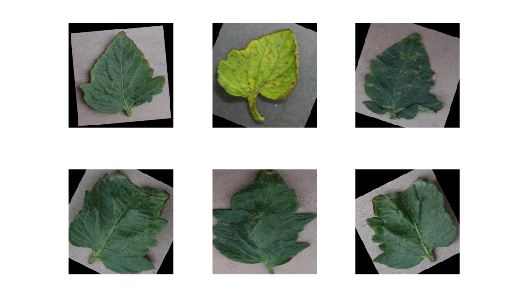

figure;
for i = 1:6
    dataTrain = read(augTrain);           %lee una imagen aumentada
    img = double(dataTrain.input{1})/255; %normaliza
    subplot(2,3,i);
    imshow(img);
end

## **Personalizar ultimas capas**

**(opcional)**

CONVERTIR RED EN UN GRAFO DE CAPAS

lgraph = layerGraph(net);

Con imagePretrainedNetwork ya está listo para transfer learning

Solo agregamos pesos por clase si hay desbalance

%calcular pesos por clase
tbl = countEachLabel(imdsTrain);
counts = tbl.Count; %cantidad de imágenes por clase
cats   = tbl.Label; %etiquetas
freq   = counts / sum(counts); %proporción de cada clase
classWeights = median(freq) ./ freq; % más peso a clases minoritarias

%crear vector de pesos en el mismo orden que las labels
classWeightsMap = containers.Map(string(cats), num2cell(classWeights));
classWeightsVec = zeros(1,numClasses);
labelsOrder = categories(imdsTrain.Labels);
for i = 1:numClasses
    classWeightsVec(i) = classWeightsMap(string(labelsOrder(i)));
end

Capas finales.

Reemplazar las **3 últimas capas** (`fc1000`, `prob(softmax)`, y agregar `classificationLayer_predictions`).

%capas finales personalizadas
newFc = fullyConnectedLayer(numClasses, 'Name','fc_new', ...
    'WeightLearnRateFactor',10,'BiasLearnRateFactor',10);

newSoftmax = softmaxLayer('Name','softmax_new');

newClassOutput = classificationLayer( ...
    'Name','classoutput', ...
    'Classes', categories(imdsTrain.Labels), ...
    'ClassWeights', classWeightsVec);

%juntar en un arreglo
newLayers = [
    newFc
    newSoftmax
    newClassOutput
];


Congelar capas iniciales para no modificar el entrnamiento de la red

%layersTransfer = freezeWeights(net.Layers(1:68));
layersToFreeze = lgraph.Layers(1:end-3);
for i = 1:numel(layersToFreeze)
    if isprop(layersToFreeze(i),'WeightLearnRateFactor')
        layersToFreeze(i).WeightLearnRateFactor = 0;
        layersToFreeze(i).BiasLearnRateFactor = 0;
    end
end

%reemplazar capas congeladas en el grafo
for i = 1:numel(layersToFreeze)
    lgraph = replaceLayer(lgraph, layersToFreeze(i).Name, layersToFreeze(i));
end


%reemplazar las 3 últimas capas (fc1000, prob, output) con las nuevas
lgraph = replaceLayer(lgraph,'fc1000',newFc);
lgraph = replaceLayer(lgraph,'prob',newSoftmax);
lgraph = addLayers(lgraph, newClassOutput);
lgraph = connectLayers(lgraph, 'softmax_new','classoutput');

## **Configurar Opciones del entrenamiento**

options = trainingOptions('adam', ... %optimizer
    'MiniBatchSize',35, ... %lotes de tamaño
    'MaxEpochs',45, ... %15 epocas para entrenar
    'InitialLearnRate',1e-5, ... %indice de aprendizaje
    'Shuffle','every-epoch', ... %se modifica en las iteraciones
    'ValidationData',augVal, ... %datos de validación
    'ValidationFrequency',max(1,floor(numel(imdsTrain.Files)/32)), ...
    'Verbose',false, ...
    'Plots','training-progress'); %mostrar progreso con gráfica

## **ENTRENAMIENTO**

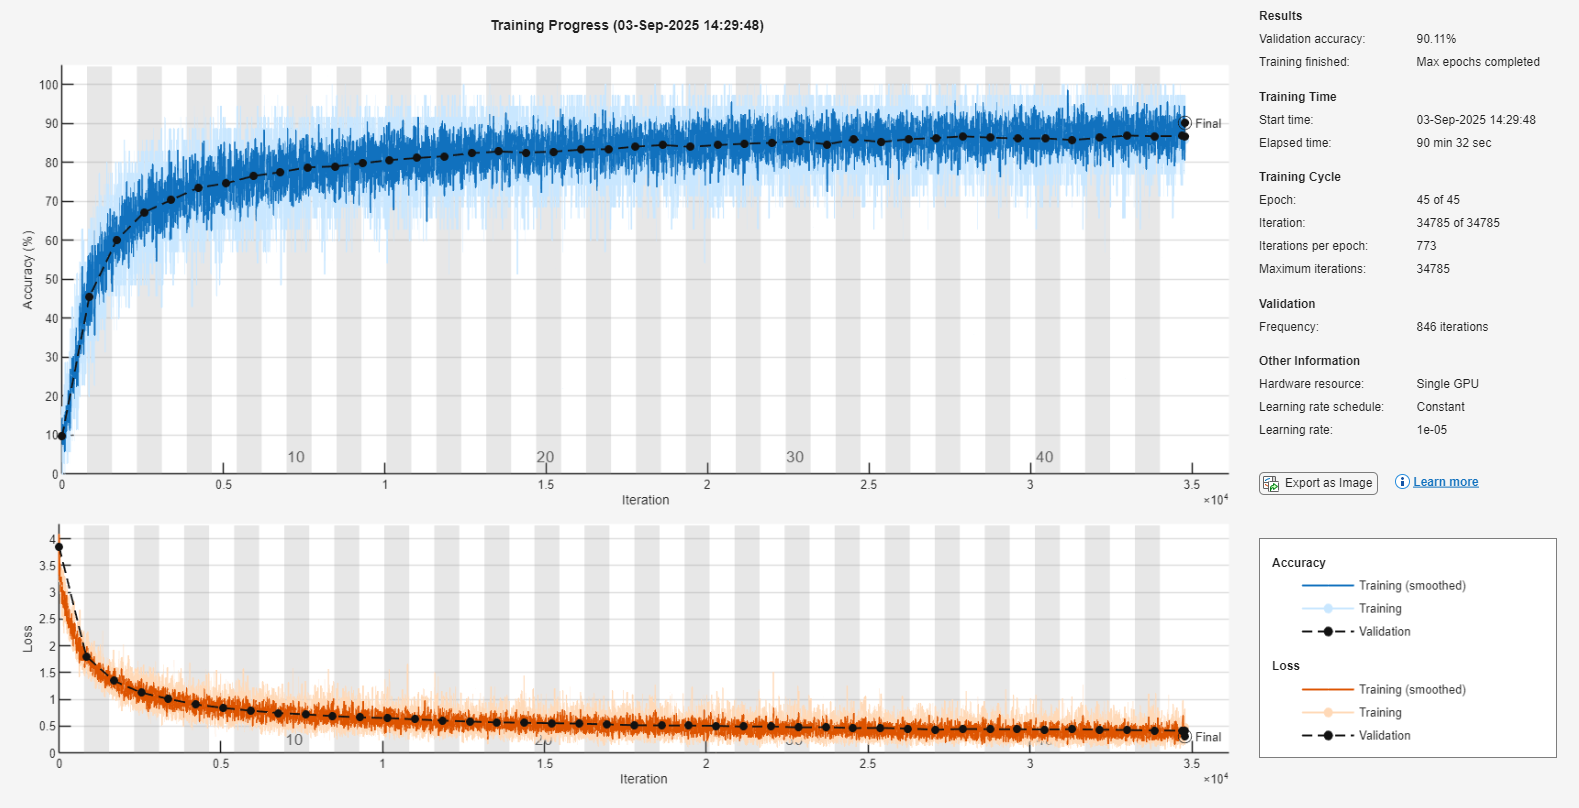

netTransfer = trainNetwork(augTrain, lgraph, options);

## **EVALUACIÓN**

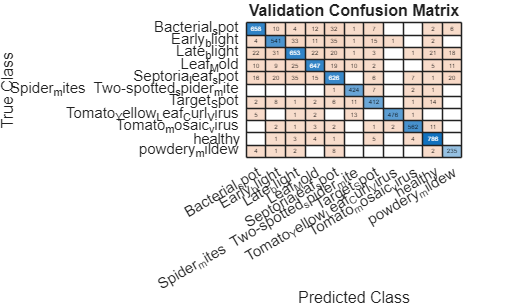

[YP_val, scores_val] = classify(netTransfer, augVal);
acc_val = mean(YP_val == imdsVal.Labels);

figure; confusionchart(imdsVal.Labels, YP_val);
title('Validation Confusion Matrix');

figure; confusionchart(imdsVal.Labels, YP_val); title('Validation Confusion Matrix');

## **Guardar modelo**

save('modeloTomate_resnet18_newdata.mat','netTransfer','labelsOrder');

exportONNXNetwork(netTransfer,'tomatoNet.onnx');
